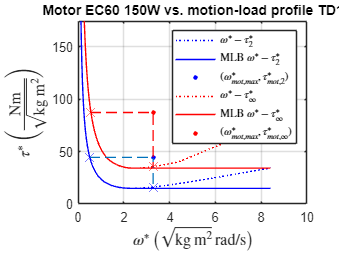

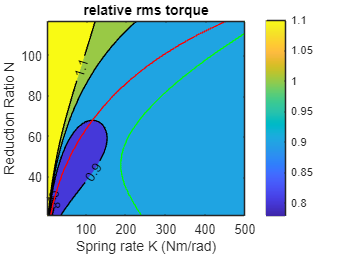

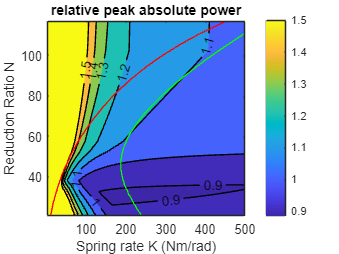

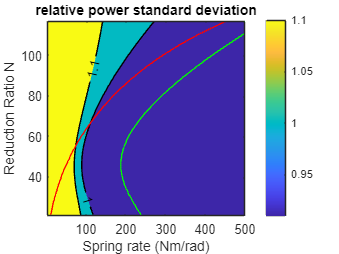

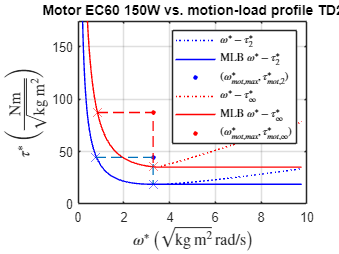

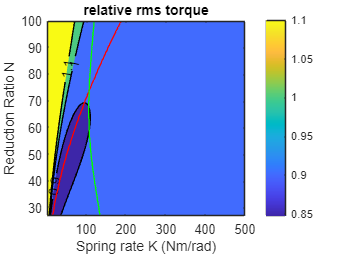

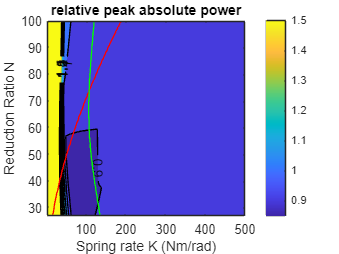

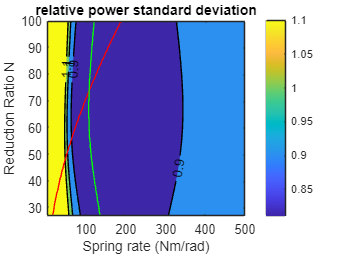

%% load and pick data
close all;
clear;
clc;

if false
    load gaitdata.mat;
    load actuatordata.mat;
    %keep only sagittal hip data
    TBL = removevars(gaitdata,{'aKsag', 'aAsag', 'mKsag_abs', 'mKsag_max', 'mKsag_min', 'mKsag_rel', 'mKsag_rms', 'pKsag_abs', 'pKsag_max', 'pKsag_min', 'pKsag_rel', 'mAsag_abs', 'mAsag_max', 'mAsag_min', 'mAsag_rel', 'mAsag_rms', 'pAsag_abs', 'pAsag_max', 'pAsag_min', 'pAsag_rel'});
else
    run load_alldata.m
end

% get length and patient identifiers
pat = TBL{:,1};
nr= length(pat);

Tgait = 1.2; %Stride period in seconds
%lowpass filter frequency
flp = 6;
flp_load = 3;
% motor
overload_nom = 1;    % motor nominal overload (increase nominal current rel to nom spec)
overload_pk = 1.96;     % motor peak overload   (increase peak current rel to nom spec)
% gearbox
eff = 1; % efficiency
assistfac = 1;  % ratio of load to assist

load actuatordata.mat
mot_id = 6;
motor_inst = motor(actuatordata(mot_id,:),overload_nom,overload_pk,[]); % select motor

for id=1:nr

    gaitprofile_inst=gaitprofile(char(pat(id)),TBL(id,:),Tgait,assistfac,[],true, 'poslp', flp, 'loadlp', flp_load);
    geareval_inst = geareval(motor_inst, gaitprofile_inst,eff,1, 'sea',true);
    geareval_inst.eval(300, 300,'Krange',[1,500], 'nNK',[100, 500]);
    %geareval_inst.eval(200, 500,'Krange',[1,1000], 'nNK',[200, 1000]);

    gaitprofiles(id) = gaitprofile_inst;
    gearevals(id) = geareval_inst;
end